# Wind Support to Bird migration

**Raphaël Nussbaumer, Baptiste Schmid, Felix Liechti**

October 20th, 2020

## Abstract

[...]

## Introduction

How do bird compensate for wind?

- strengh and direction of wind

- prefered direction

- altitude

- time/season

- timing of deparute: are bird compensating more early in the night?

- (- specie of bird, size)

## Methods

**Weather radar data: bird vector speed and density**

Bird density, orientation and speed for 37 weather radars in western Europe are downloaded from the ENRAM repository (ref) and processed as explained in Nussbaumer (2020) ([https://doi.org/10.1101/2020.10.13.321844](https://doi.org/10.1101/2020.10.13.321844)). The final dataset consisting of bird density (ρ) [bird/km^3], flight speed following the east-west component (`u`)  and south-north component (v) [m/s] at 15min resolutions, 200m bin altitude (0-5km) for each radar are available on zenodo [https://zenodo.org/record/3610185.](https://zenodo.org/record/3610185.)

**Climate Reanalaysis: Wind vector speed at pressure level**

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind are downloaed from the ERA5 reanalysis (ref) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). Both components (`U` and `V`) are linearly interpolated (time-space 4D) at each datapoint of the weather radar data. 

load('../2018/data/dc_corr.mat','dc'); 

**Ground and air speed**

Birds' groundspeed ($V_g$) and airspeed ($V_a$) can be computed respectively with


$$V_g =\sqrt{u^2 +v^2 }$$


and

 $V_a =\sqrt{{\left(u-U\right)}^2 +{\left(v-V\right)}^2 }$.

We recompute the ground speed similarly to Nussbaumer (2020) but remove the interpolation component of the speed because we are not interested in the spatio-temporal consistency of the data, but rather limiting our analysis to only original data size. 

for i_d=1:numel(dc)
    % Compute the n/s and e/w componenent of the flight speed
    dc(i_d).u = dc(i_d).ff .* sind(dc(i_d).dd); % m/s | 0� is north and 90� is west. -> u is east (+) - west (-)
    dc(i_d).v = dc(i_d).ff .* cosd(dc(i_d).dd); % m/s  -> v is north (+) - south (-)

    % Remove data not cleaned for density (e.g. rain). 
    id = isnan(dc(i_d).dens3) | dc(i_d).dens3==0;
    dc(i_d).u(id)=nan;
    dc(i_d).v(id)=nan;

    coef=8-2.4;
    cc = dc(i_d).insect.*coef;
    
    airspeed_u = dc(i_d).u-dc(i_d).windu;
    airspeed_v = dc(i_d).v-dc(i_d).windv;
    
    v_adc = sqrt((dc(i_d).u-dc(i_d).windu).^2 + (dc(i_d).v-dc(i_d).windv).^2);
    
    dc(i_d).u2 = airspeed_u.*(cc+v_adc)./v_adc + dc(i_d).windu;
    dc(i_d).v2 = airspeed_v.*(cc+v_adc)./v_adc + dc(i_d).windv;
end

v_a=nan(numel(dc(1).time), numel(dc(1).alt), numel(dc)); v_g=v_a; dens = v_a; v_w =v_a;
for i_d=1:numel(dc)
    v_g(:,:,i_d) = sqrt(dc(i_d).u2.^2 + dc(i_d).v2.^2); % ground speed
    v_a(:,:,i_d) = sqrt((dc(i_d).u2-dc(i_d).windu).^2 +(dc(i_d).v2-dc(i_d).windv).^2); % air speed
    v_w (:,:,i_d) = sqrt(dc(i_d).windu.^2 + dc(i_d).windv.^2); % wind speed
    dens(:,:,i_d) = dc(i_d).dens4;
end

## Results

**Overall trend**

First, I'm looking at confirming basic trend which are already known to check that all the methodolgy and dataset are correct. 

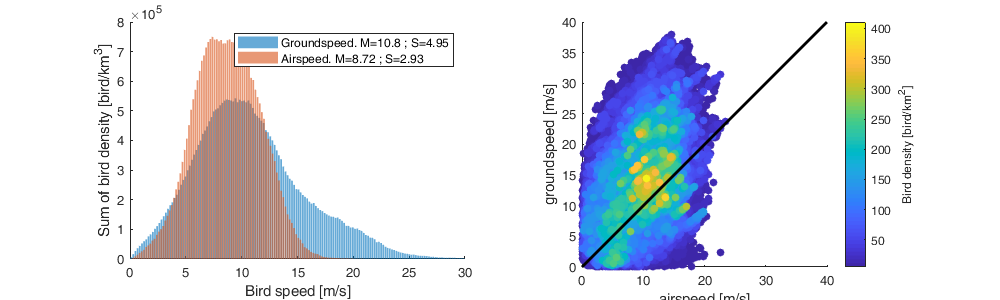

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g, dens);
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a, dens);
bar(e,h,'FaceAlpha',0.6);
%plot(0:30,normpdf(0:30,Mg,Sg)./max(normpdf(0:30,Mg,Sg))*max(tmp3),'-r');
%plot(0:30,normpdf(0:30,M,Sa)./max(normpdf(0:30,M,Sa))*max(tmp3),'-r');
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel('Bird speed [m/s]');
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);


subplot(1,2,2); hold on;
[~, id] = sort(dens(:)); id2 = id(dens(id)>5); % only keep density >5bird/km^2 for computing reason
scatter(v_a(id2),v_g(id2),[],dens(id2),'filled'); axis tight equal;
plot([0 40],[0 40],'k','LineWidth',2)
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; c.Label.String='Bird density [bird/km^2]';

Histograms of speed (a) and (b) are normalized by the density of bird.

(a) Bird move at around 11 m/s (sd=5) while their air speed is actually smaller and more restricted to a speed of 8.7m/s (sd:3).

(b) There are more birds in the air (high bird density) when their ground speed is higher than their airspeed, in other term when the wind is supporting their movement. 

**Season Specific**

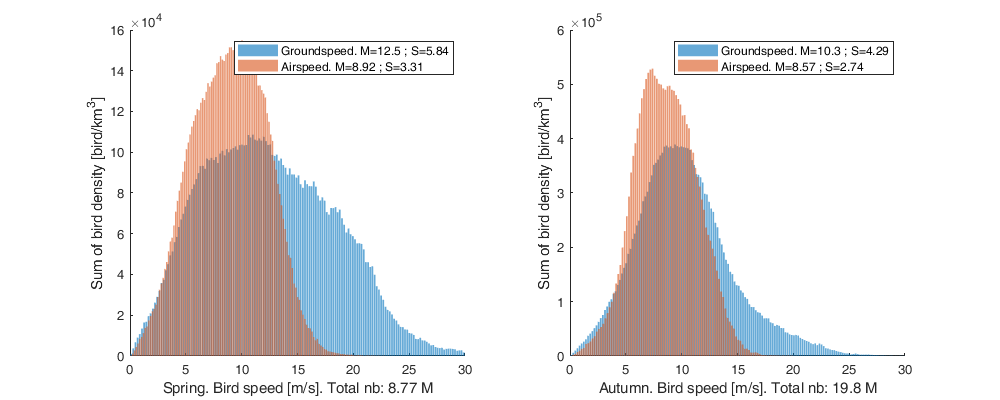

figure('position',[0 0 1000 400]);

subplot(1,2,1); hold on;
id_t = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-June-2018');
[e,h,Mg,Sg] = histvdens(v_g(id_t,:,:),dens(id_t,:,:));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_t,:,:),dens(id_t,:,:));
bar(e,h,'FaceAlpha',0.6);
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel(['Spring. Bird speed [m/s]. Total nb: ' num2str(sum(h)/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(1,2,2); hold on;
id_t = dc(1).time>datetime('1-Aug-2018') & dc(1).time<datetime('1-Nov-2018');
[e,h,Mg,Sg] = histvdens(v_g(id_t,:,:),dens(id_t,:,:));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_t,:,:),dens(id_t,:,:));
bar(e,h,'FaceAlpha',0.6);
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel(['Autumn. Bird speed [m/s]. Total nb: ' num2str(sum(h)/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

While the bird are moving with quite different ground speed (blue) regime between Spring (left) and Autumn (right), their actual airspeed (red) is impresively similar. 

**Altitude Specific**

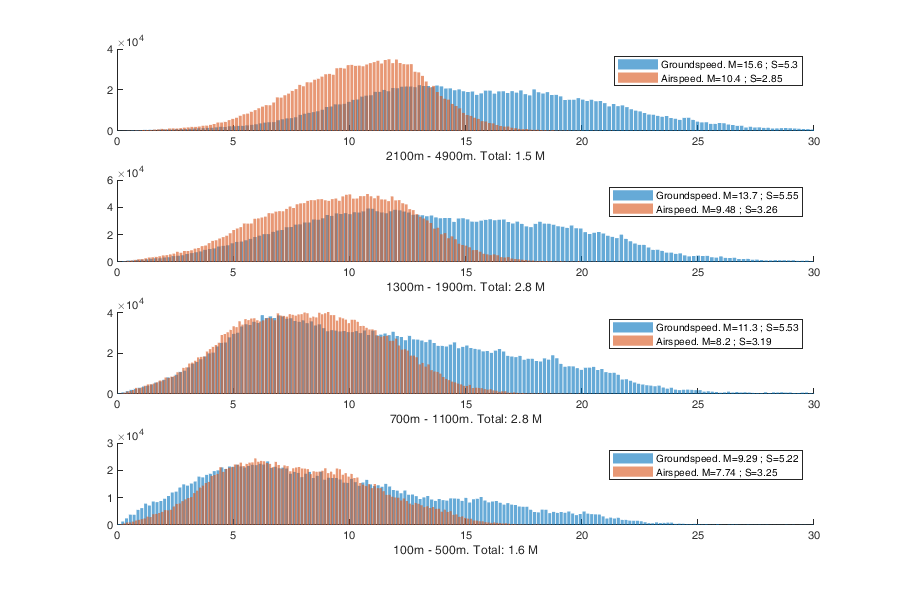

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
id_t = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-June-2018');
for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_t,id_a,:),dens(id_t,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_t,id_a,:),dens(id_t,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]);
end

Note that the groupement of altitude bin for the figure are not regular.  

In spring, WR are measureing an increase of ground speed with altitude. The wind data seems to explain at least partly this increase because airspeed is not increasing as much as groundspeed. However, there is still an increase of airspeed with altitude. Are the bird really flying faster or is there more directional movement with altitude explaining the difference of airspeed?

We can also note that birds are flying high (see Total in Figure) which is proba to benefit from higher windspeed. 

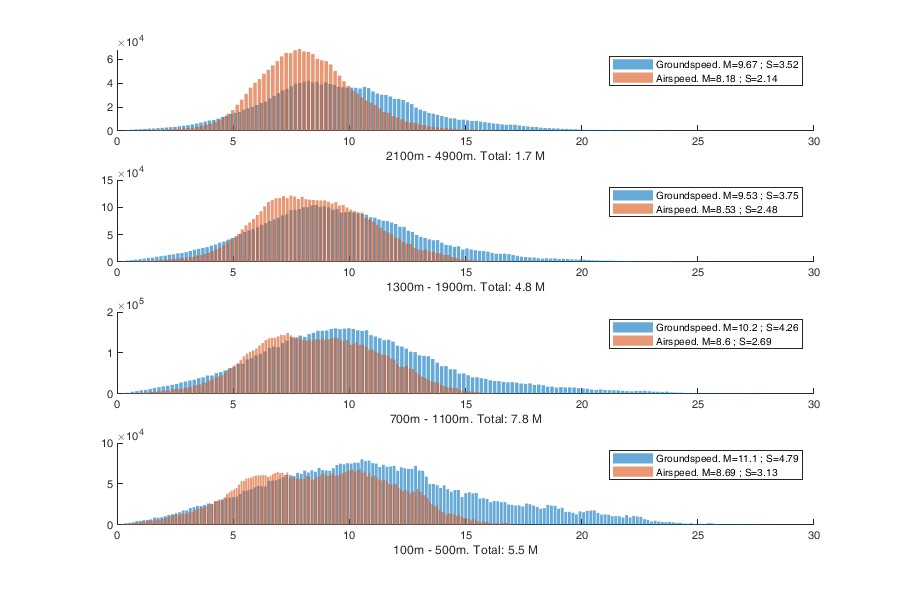

figure('position',[0 0 900 600]);
id_t = dc(1).time>datetime('1-Aug-2018') & dc(1).time<datetime('1-Nov-2018');
for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_t,id_a,:),dens(id_t,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_t,id_a,:),dens(id_t,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]);
end

Autumn pattern is less variability with altitude. Groundspeed and airspeed reduces very slightly with altitude.

**Geographical **

We can test the geographical variation. 

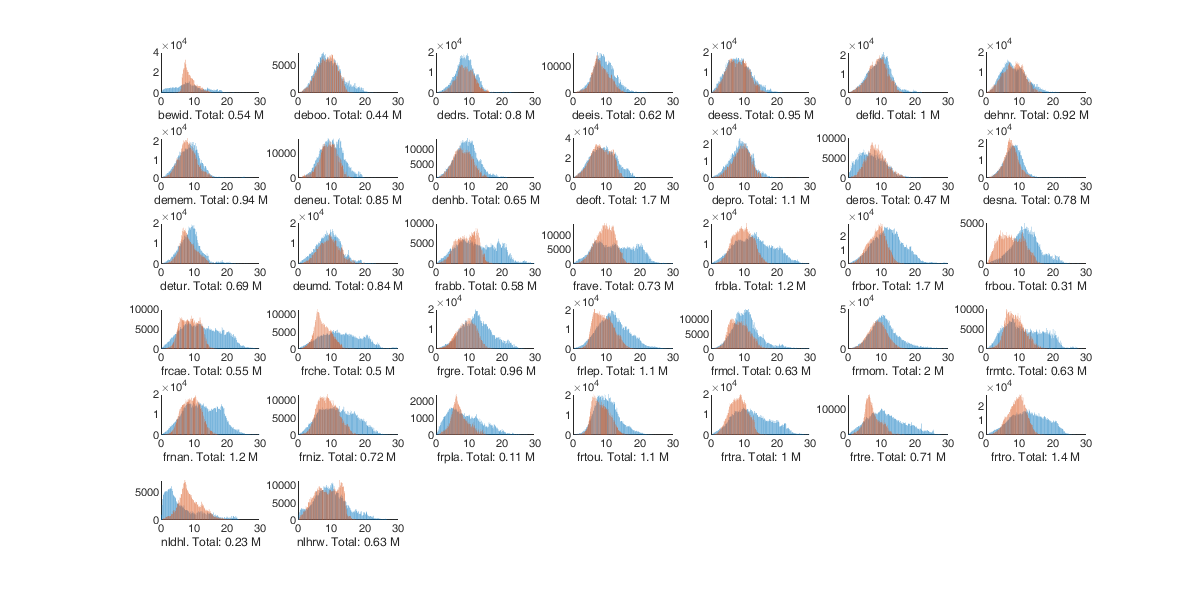

figure('position',[0 0 1200 600]);
for i_d= 1:numel(dc)
    subplot(6,7,i_d); hold on
    [e,h,Mg,Sg] = histvdens(v_g(:,:,i_d),dens(:,:,i_d));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(:,:,i_d),dens(:,:,i_d));
    bar(e,h,'FaceAlpha',0.6);
    mga(i_d) = Mg-Ma;
    % legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ dc(i_d).name '. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]);
end

There is a very strong difference visible at the country level. In Germany, the difference between airspeed and ground speed is very small while in French, the pattern observed earlier is most consistant.

We plot below the difference in ground speed before and after the cleaning performed to checked that the artifact seen above is not due to the post-processing. 

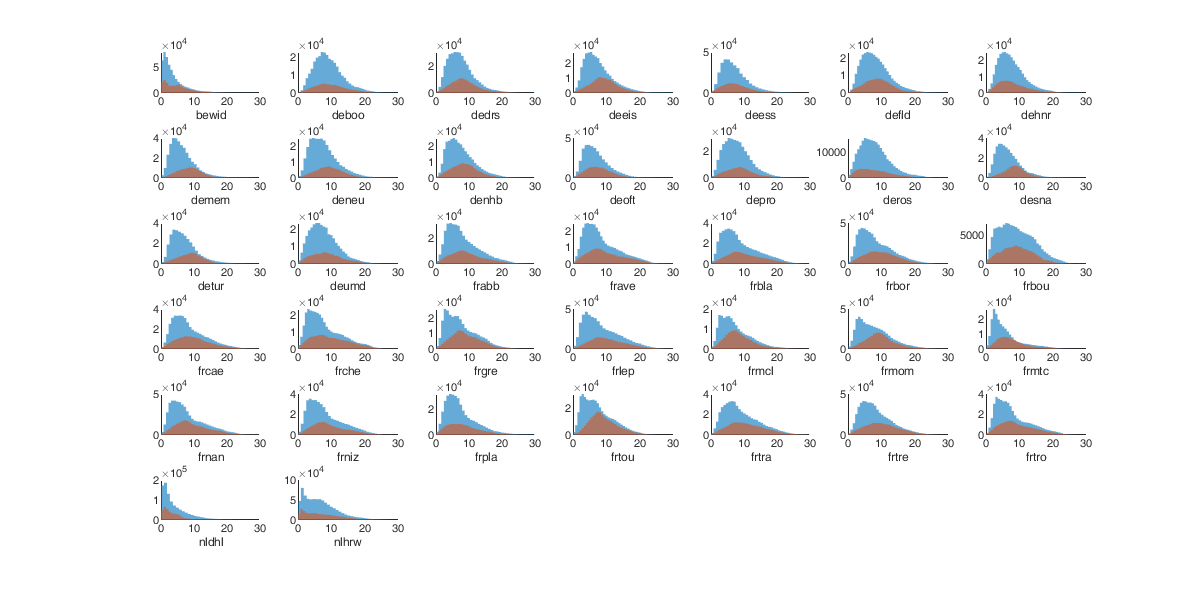

figure('position',[0 0 1200 600]);
%id_t = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-May-2018');
id_t = dc(1).time>datetime('1-Jan-2018');
for i_d=1:numel(dc)
    subplot(6,7,i_d); hold on
    %histogram(dc(i_d).dd(id_t,:),50); xlim([0 360])
    %a=atan2d(dc(i_d).v(id_t,:),dc(i_d).u(id_t,:) ); a(a<0)=a(a<0)+360; histogram(a,50); xlim([0 360])
    histogram(dc(i_d).ff(id_t,:),50,'EdgeColor','none'); xlim([0 30])
    histogram(sqrt( dc(i_d).u2(id_t,:).^2 + dc(i_d).v2(id_t,:).^2),50,'EdgeColor','none'); xlim([0 30])
    xlabel(dc(i_d).name); 
end

Blue: Original data, red: post-cleaning (insect removal).

**Progress of night**

I also checked the pattern along the night. We use the NNT which normalize the time between sunset and sunrise between -1 and 1. 

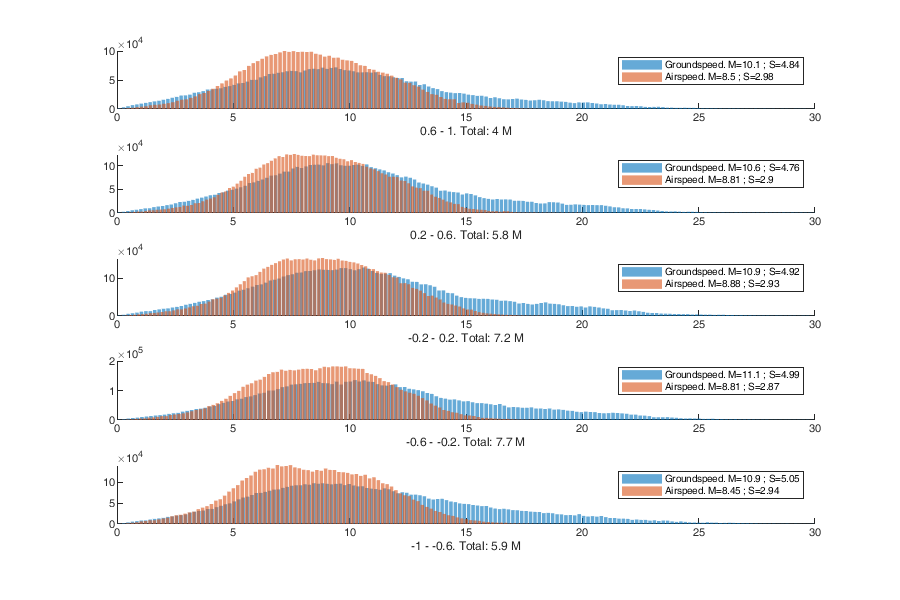

figure('position',[0 0 900 600]);
NNT = datenum(repmat(dc(1).time',1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;
a=-1:0.4:1;
for i_a= 1:numel(a)-1
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1),[1 3 2]),1,25,1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_a),dens(id_a));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_a),dens(id_a));
    bar(e,h,'FaceAlpha',0.6);
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ num2str(a(i_a)) ' - ' num2str(a(i_a+1)) '. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]);
end

## Appendix

**Local Functions**

function [e,h,M,S] = histvdens(v,dens,bin)
    if ~exist('bin','var'), bin = 200; end
    id=~isnan(v)&~isnan(dens);
    [Y,edge] = discretize(v(id),bin); 
    [G,ID] = findgroups(Y);
    h=zeros(numel(edge)-1,1);
    h(ID) = splitapply(@sum, dens(id), G);    
    e = 0.5 * (edge(1:end-1) + edge(2:end));
    M = nansum(v(id).*dens(id))/nansum(dens(id));
    S = nanstd(v(id & dens>0),dens(id & dens>0));
end